# Lab 1

Gabriel Casciano, 500744076

Aleksandar Nikolovski, 500572171

Khayyam Butt, 500501040

The subject of study for this lab is Bayesian decision theory.

The training set being used is the iris training set.

## Part 1

## Question 1:

Using a single discriminant function $g(x_2)$, design a 2 class minimum-error-rate classifier (dichtomizer) from the given data, to classift **IRIS** samples into to either *Iris Setosa* or *Iris Versicolor*, according to the feature: *Sepal Width*.

This is a 2 class, single discriminant function classifier.

## Question 2:

Using the shell program *lab1.m*, write a program that will take individual sample values as the input and will return the *posteriror probabilities* and the values of $g(x_2)$.

Refer to the file named: **lab1_1.m** for this portion of the report.

## Question 3:

Identify the class labels for the feature values using your program, and indicat their respective posterior probabilities and discriminant values: $x_2 = [3.3, 4.4, 5.0, 5.7, 6.3]$.

x = [3.3, 4.4, 5.0, 5.7, 6.3];

Threshold_x1 = 0;

for i = 1 : length(x)
    [posterior(i,:), discriminant(i,:)] = lab1_1(x(i), trainingSet);
    fprintf('For x(%d), value of: %.1f \n', i, x(i));
    fprintf('Posteriors: %f, %f \n', posterior(i,1), posterior(i,2));
    fprintf('Discriminant: %f \n', discriminant(i));
    if(Threshold_x1 < discriminant(i,:))
        fprintf('Iris-setosa');
    else
        fprintf('Iris-versicolor');
    end
    fprintf('\n \n');
end

For x(1), value of: 3.3 


Posteriors: 0.765714, 0.234286 


Discriminant: 0.531427 


Iris-setosa

For x(2), value of: 4.4 


Posteriors: 0.999953, 0.000047 


Discriminant: 0.999907 


Iris-setosa

For x(3), value of: 5.0 


Posteriors: 1.000000, 0.000000 


Discriminant: 1.000000 


Iris-setosa

For x(4), value of: 5.7 


Posteriors: 1.000000, 0.000000 


Discriminant: 1.000000 


Iris-setosa

For x(5), value of: 6.3 


Posteriors: 1.000000, 0.000000 


Discriminant: 1.000000 


Iris-setosa

## Question 4:

Arrive at a optimal threshold ($T_{h_1}$) that seperates classes $\omega_1$ and $\omega_2$ (theoretically or experimentally). Justify your results.

The following software was used to arrive an optimal threshold for $T_{h1}$

**Variables**

These are the variables that will be used to classify the flower based on the output discriminant function .

$error_{x_2}$ is used to calculate the error for $threshold_{x_2}$

error_x2 = 0;
threshold_x2 = 0;

**Calculations** 

**When Demoing remember that an error was found in the percent error calculations, the values here are different than the ones that were submitted originally in the lab **

This loop is being used to calculate the disctiminat function for all of the data set in the training set. The training set is being used because it has datalabels associated with each data set, thus making it easier to determine whether or not the correct decision has been made.

The discriminant and posterior probabilities for feature 1 & 2 are calculated via the **lab1_1.m** & **lab1_2.m** scripts.

for i = 1 : length(trainingSet)
    [posterior_x2(i,:), g_x2(i,:)]= lab1_1(trainingSet(i, 2), trainingSet);
    
    %the discriminant of x1 & x2 are being appended to the 6th and 7th
    %columns of the training set to make for easier comparison.
    trainingSet(i, 6) = g_x2(i);
    
    %the following logic is being used to determine whether or not the
    %correct decision has been made
    if((trainingSet(i,6) > threshold_x2 && trainingSet(i,5) == 1) || (trainingSet(i,6) < threshold_x2 && trainingSet(i,5) == 2))
       error_x2 = error_x2 + 1;
    end
end

Here the percent error is being calculated

error_x2 = 1 - (error_x2 / length(trainingSet));
fprintf('Percent error, x2: %.2f%c', (error_x2 * 100), '%');

Percent error, x2: 16.00%

The following logic was applied to determine if a correct decision was made: $(trainingSet_{i,6} > threshold_{x_2} \bullet trainingSet_{i,5} = 1) + (trainingSet_{1,6} < threshold_{x_2} \bullet trainingSet_{i,5} = 2)$ If this statement yielded a true result then $error_{x_2}$ was incremeted since this variabled acted as both counter and percent error.

Based on the percent error that was calulcated, $T_{h_1} = 0$ is an acceptable threshold value for classification between $\omega_1$ & $\omega_2$ based on their *Sepal Width*.

## Question 5:

Suggest how $T_{h1}$ would be affected if a higher penalty is associated with classifying class $\omega_2$ as a class $\omega_1$ - show with experiment.

If a larger penalty is associated with classifying a *Iris Versicolor* as an *Iris Setosa* the Threshold, $T_{h_1} would be forced to shift down below 0. As it shifts down, you would be able to notice that the classifiers error rate relative to *Iris Setosa* is going up, but relative to *Iris Versicolor* it is going down. 

By adjusting the classifier to be penalized more for classifying $\omega_2$ as $\omega_1$ more *Iris Versicolor* flowers are going to be classified as an *Irirs Setosa*.

To demonstrate this the threshold is going to bemore biased in the direction of $\omega_2$ so that it is less likely to classify an $\omega_2$ as an $\omega_1$. 

error_x2 = 0;
threshold = [-.2,-.4,-.5,-.6];
for j = 1 : length(threshold)
    for i = 1 : length(trainingSet)
        [posterior_x2(i,:), g_x2(i,:)]= lab1_1(trainingSet(i, 2), trainingSet);
        trainingSet(i, 6) = g_x2(i);

        if((trainingSet(i,6) < threshold(j) && trainingSet(i,5) == 1) || (trainingSet(i,6) > threshold(j) && trainingSet(i,5) == 2))
           error_x2 = error_x2 + 1;
        end
    end
    
error(j, :) = 1 - error_x2 / length(trainingSet);
fprintf('Percent error of Iris Versicolor, x2: %.2f%c based on Threshold value: %.2f \n', (error(j) * 100), '%', threshold(j));
end

Percent error, x2: 84.00% based on Threshold value: -0.20 
Percent error, x2: 66.00% based on Threshold value: -0.40 
Percent error, x2: 42.00% based on Threshold value: -0.50 
Percent error, x2: 18.00% based on Threshold value: -0.60 


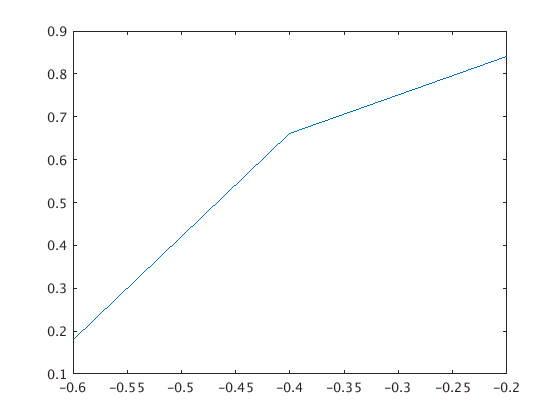


plot(threshold, error);

## Question 6:

Adjust your program to accept *Sepal Length* as the discriminating feature $g(x_1)$. Suggest which of the two features ($x_1$, $x_2$) might be a better choice for sperating the two classes $\omega_1$ and $\omega_2$. Jutify.

For the adjusted program please refer to the file **lab1_2.m**, refer to the file called **lab1_3.m** for the full calculations.

Assuming $T_{h_2} = 0$ aswell (based on experimental evidence). If $error_{x_1}$ is calculated the same as $error_{x_2}$ for their respective threshold values then, based on their precent errors:

run Lab1_3;

fprintf("Percent error, x1: %.2f%c \n", (error_x1 * 100), '%');
fprintf("Percent error, x2: %.2f%c", (error_x2 * 100), '%');

The input character is not valid in MATLAB statements or expressions.


It is clear that feature $x_1$ has a lower percent error making it the more reliable feature.